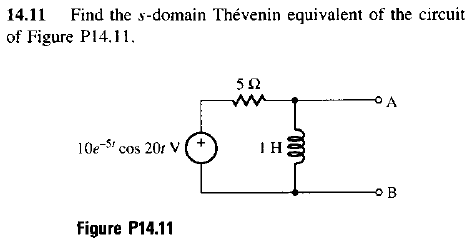

clc, clear, close all
format short g
syms t s

vf = 10*exp(-5*t)*cos(20*t); %[V]
vm = 10; %magnitud
s = -5+20*j; %frecuencia compleja

z1 = 5;
z2 = s;

primero calculamos la tension de thevenin que esta dada por el siguiente divisor de tensión

vth = (z2/(z1+z2))*vm %complejo

vth =            10 +        2.5i


vth_fasor = [num2str(abs(vth)),' ∟', num2str(angle(vth)*180/pi),'°', ' V'] %fasor

vth_fasor = '10.3078 ∟14.0362° V'

Lo verificamos en el simulador

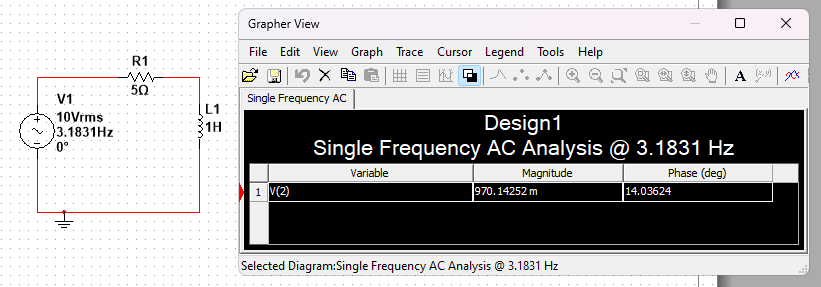

Ahora calculamos la resistencia thevenin

rth = 1/(1/(z1)+1/(z2))

rth =             5 +       1.25i


rth_polar = [num2str(abs(rth)),' ∟', num2str(angle(rth)*180/pi),'°', ' Ω'] %polar

rth_polar = '5.1539 ∟14.0362° Ω'